# Organizing and Accessing Information

[⇦ Overview](matlab: open("Overview.html"))

A list is an extremely common structure in programming. Fundamentally, it is an ordered set of elements. The details of the implementation of lists vary across programming languages, but the ordering always allows referencing by index in some fashion. One of the other challenges for lists is locating a value in a list or determining that there is no such value in the list. Sometimes, more than one bit of information should be saved together such as in a table or key/value pair. This script explores several common formats for organizing and accessing information in MATLAB.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## Arrays

Arrays are the most [fundamental representation](https://www.mathworks.com/help/matlab/matrices-and-arrays.html) of data in MATLAB. This is an excellent choice whenever all the data you plan to work with is the same type. Arrays were introduced in the [Fundamentals of Programming](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming) module, 

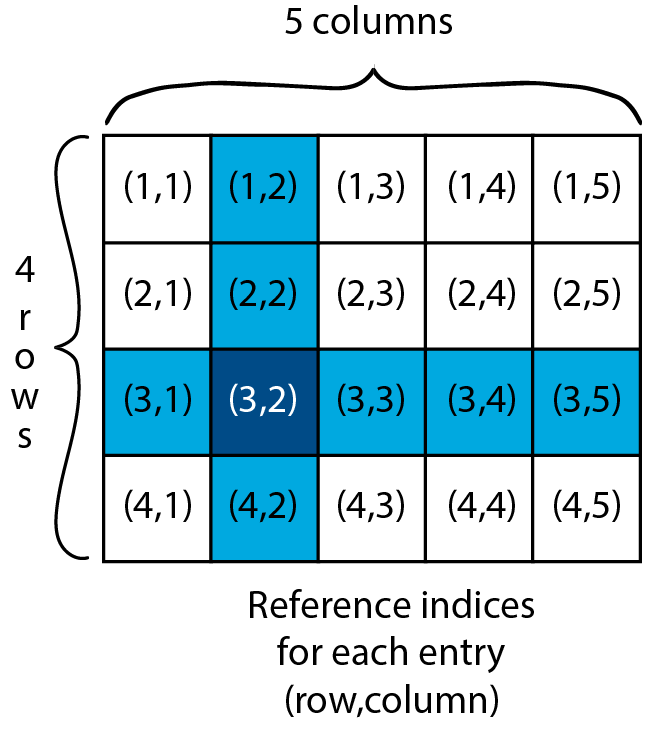           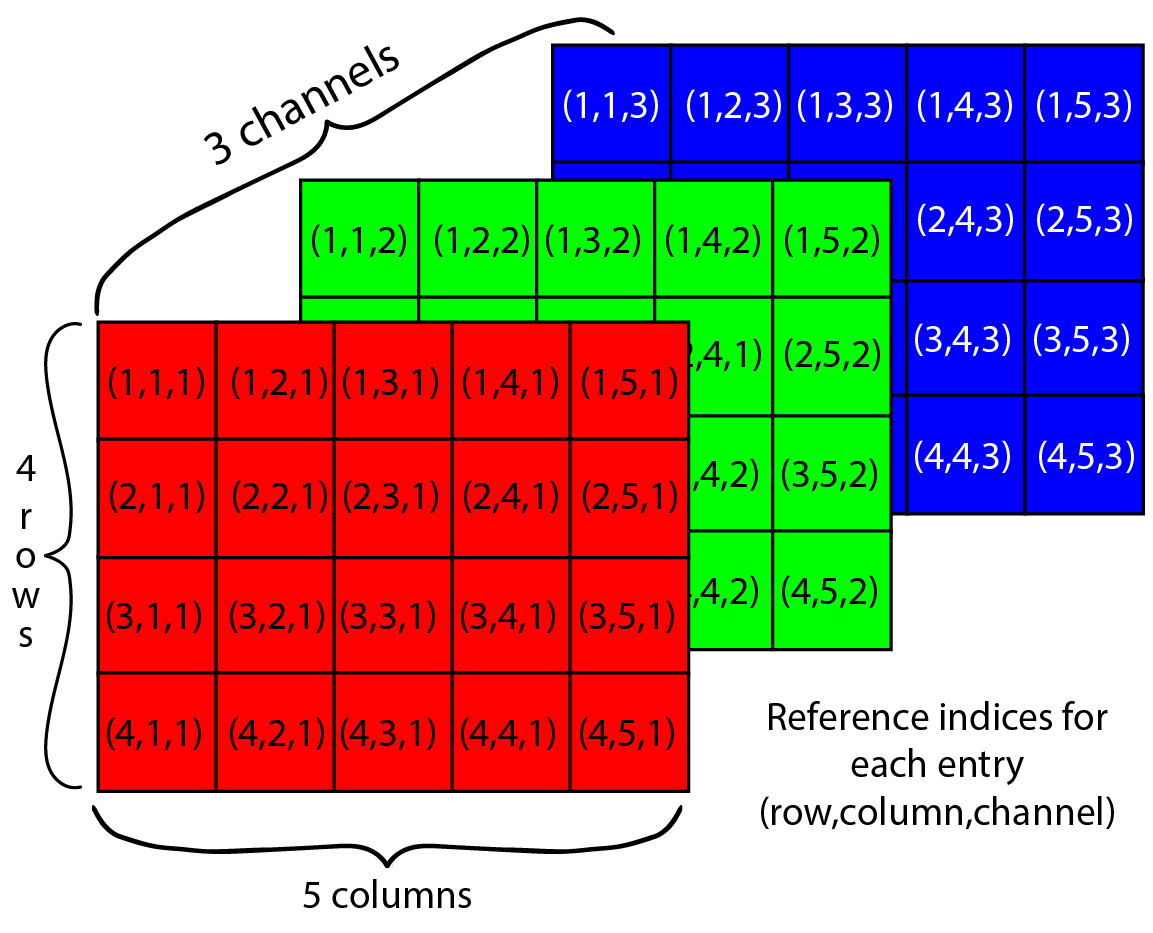 

and are discussed in [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) regarding the [creation](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=4) of arrays, [getting information in and out](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=5) of arrays, and [performing calculations](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted#module=6) on arrays. You can explore even more in the self-paced online course [MATLAB Fundamentals](https://matlabacademy.mathworks.com/details/matlab-fundamentals/mlbe).

  **Try**. 

- Create a `3x5` array named `M` containing [random](matlab: doc rand) numbers.

- Create a `2x2` array named `S` containing the strings `"This"`, `"is"`, `"an"`, and `"array"`.

- Try to create a `2x2` array named `C` containing the character arrays `'This '`, `'is'`, `'an'` and `'array'`. What happens? What happens if you use `'This'` instead of `'This '?`

- Create a `3x1` array named `V` containing an integer, say `int8(3)`, and two floating point numbers such as `4.7` or `pi`. What happens? Does it matter what order you put the numbers in?

- Create an array 

            What happens? Can you use the documentation page for `char` to figure out what is going on? 

% Do your experimenting here


### Using Logical Indexing with Arrays

% Set up matrices to use in examples
M = rand(5);
S = ["This" "is" "not" "a" "sentence" "."];

When you already know which values you want, it is easy to access a particular element like

S(1,1)

or

S(end)

Frequently you may not know which indices correspond to the elements you want, however. You can use logical indexing to identify values according to any logical test:

% Print the values in the random matrix M
M
% Create a logical matrix where the (i,j)th entry is true if M(i,j)>0.5
% and false if M(i,j) <= 0.5
M > 0.5
% Reset all the values where M>0.5 to 0
M(M>0.5) = 0 

   **Try**. 

- Reset all the values where `M==0` to `16`.

- Reset all the values in `S` which contain an `"s"` to be `"box"`.

** Application: Sea Surface Temperatures.**

Explore the data file:

ncdisp("SEAFLUX-OSB-CDR_V02R00_SST_D19900117_C20160820.nc")

** Exercise 1**.

a) What data type is the variable `lat` stored in?

b)  What are the units of `sea_surface_temperature`?

c) What value is listed for a missing value of `sea_surface_temperature`?

d) How is time stored?

#### Load the Sea Surface Temperature Data

Using the metadata that we just explored, use `ncread` to load the data that is included in the data files for the 17th of each month in 1990, e.g., January 17, 1990, February 17, 1990, .... 

sstData = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900117_C20160820.nc","sea_surface_temperature");
sstData2 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900217_C20160820.nc","sea_surface_temperature");
sstData3 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900317_C20160819.nc","sea_surface_temperature");
sstData4 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900417_C20160819.nc","sea_surface_temperature");
sstData5 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900517_C20160819.nc","sea_surface_temperature");
sstData6 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900617_C20160820.nc","sea_surface_temperature");
sstData7 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900717_C20160820.nc","sea_surface_temperature");
sstData8 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900817_C20160820.nc","sea_surface_temperature");
sstData9 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900917_C20160819.nc","sea_surface_temperature");
sstData10 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19901017_C20160819.nc","sea_surface_temperature");
sstData11 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19901117_C20160819.nc","sea_surface_temperature");
sstData12 = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19901217_C20160820.nc","sea_surface_temperature");

sstAll = cat(3,sstData,sstData2,sstData3,sstData4,sstData5,sstData6,sstData7,...
    sstData8,sstData9,sstData10,sstData11,sstData12);

clear sstData*

% The times, latitude data, and longitude data are identical in each file
tData = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900117_C20160820.nc","time");
latData = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900117_C20160820.nc","lat");
lonData = ncread("SEAFLUX-OSB-CDR_V02R00_SST_D19900117_C20160820.nc","lon");


   **Try**. Visualize the sea surface temperatures as a scaled image. Because you are currently exploring the data, try looking at just the first time slice:

imagesc(sstAll(:,:,1))

 **Reflect. **

- Does this image look like a familiar map of the world? Why or why not?

  **Try**. Recognizing that the data doesn't initially match the shape that you probably expect, try using `pagetranspose` to transpose just each time slice individually. Does that help your results?

sstImage = pagetranspose(sstAll);
imagesc(sstImage(:,:,1))

Not quite. To present a standard image of the world where north is up, you need one more transformation to flip the image up/down. This can be done using `flipud. `

sstImage = flipud(pagetranspose(sstAll));

imagesc(sstImage(:,:,1))

** Exercise 1, continued**

e) Using `datetime` and `years`, `days`, `hours`, `seconds`, etc, create a vector of the dates and times in `tData`. Save this vector as the variable `tJan`.

  **Pro-tip**. Remember that you can use a documentation search to find command syntax:

% Set tJan to be midnight on Jan 1, 2022
tJan = datetime([2022 01 01 00 00 00]);

Observe that the `tJan` vector can be modified to create a vector `tAll` by making additional copies of `tJan` with updated month values:

tAll = repmat(tJan,1,12);
for m = 2:12
    tAll(:,m).Month = m;
end
tAll = reshape(tAll,[],1);

#### Plot the Sea Surface Temperature Data

% figure
tempMax = max(sstImage,[],"all");
tempMin = min(sstImage,[],"all");
scalingFactor = 235/(tempMax-tempMin);

sstImageScaled = (sstImage-tempMin)*scalingFactor+10;
sstImageScaled(isnan(sstImage)) = 140;
load coastlines
coastShifted = [mod((360+coastlon),360)*4 360-coastlat*4];
for k = 1:length(tAll)
    image(sstImageScaled(:,:,k))
    hold on
    plot(coastShifted(:,1), coastShifted(:,2),".","MarkerSize",3)
    hold off
    title("Ocean Surface Temperature, "+string(tAll(k)))
    pause(0.2)
end

### Using Linear Indexing with Arrays

Although arrays are conceptually multi-dimensional, knowing something about how an array is stored in memory can offer additional possibilities for indexing. Since MATLAB is [column-major](matlab:open('./Memory.mlx')) by default, a single value indexing into an array is treated as a simple memory offset calculation into the linearly-stored array. 

% Create a 4x4 magic square
M = magic(4)
% Select and display the 1st element of the 3rd column
% which is the 2*4+1 = 9th linearized element
M(9)
% Linearize and display the matrix M
M(:)

  **Try**. 

Before reshaping `tAll`, it was an `8x12` matrix of distinct elements:

tAll = repmat(tJan,1,12);
for m = 2:12
    tAll(:,m).Month = m;
end
size(tAll)

- Determine the linear indices necessary to extract all the times on April 17, 1990 from this form of `tAll`. What is a reasonable name for the new vector?

- What happens if you make the same call after reshaping `tAll`, as above, into a column vector?

## Tables

A table is a collection of tabular data where each row contains one entry in each column-oriented variable. 

** Application: Working with Timestamped Numerical and Categorical Data.**

First, read in the tabular data from the comma-separated value file: `WkOfSolarPowerGeneration.csv`.

solar = readtable("WkOfSolarPowerGeneration.csv")

The first column is a `datetime` and the second column is a `double`, but what is the third column of data?

class(solar.Sun_up)

Apparently, `readtable` couldn't identify the data type of the `Sun_up` column, so it has been pulled into MATLAB as the general cell array data type. However, we can fix that by supplying additional information. By quick inspection, the only values that `Sun_up` takes are `"yes"` and `"no"`. It should be a categorical data type:

solar.Sun_up = categorical(solar.Sun_up)
class(solar.Sun_up)

One useful feature of tables is the `summary` command which attempts to provide a summary of the information in the table. The type of summary will depend on the data type of that column. 

summary(solar)

Let's investigate these missing values. 

idx = find(ismissing(solar.AC_kw))

Look at the values near the missing value:

solar.AC_kw(idx-3:idx+3)

In this case it seems very legitimate to fill in this missing data with a copy of the previous value:

solar.AC_kw(idx) = solar.AC_kw(idx-1);

** Exercise 2**.

Decide how to account for the missing values in `solar.Sun_up`. Does it make the most sense to use `fillmissing` or `rmmissing` in this case? 

** Exercise 3**.

a) How often were the solar power arrays generating power when the sun was down? What was the total power generated while the sun was down?

b) On which days were the solar power arrays not generating power when the sun was up?

c) What fraction of the time were the solar power arrays not generating power when the sun was up?

## Structure Arrays & Cell Arrays

A structure array is commonly known as a structure or even simply as a struct. [Structure arrays](https://www.mathworks.com/help/matlab/structures.html) are one way to organize collections containing different types of data. You can access data inside a structure using dot notation in the form `structName.fieldName`.

** Application: A Structure Array of Metadata**

When we first looked at the sea surface temperature data, we used the command `ncdisp` to display the metadata. We can use other commands to generate other types of data structures from the same information.  Using `ncinfo` rather than `ncdisp` will generate a structure array including the same information:

Flux = "SEAFLUX-OSB-CDR_V02R00_FLUX_D19900611_C20160824.nc";
SST = "SEAFLUX-OSB-CDR_V02R00_SST_D19900117_C20160820.nc";
fileLoc = Flux;
fInfo = ncinfo(fileLoc)

Then we can access fields within the structure using dot notation. Some of the fields contain information that we could already see in the summary presentation:

fInfo.Format

but others contain structures themselves with even more information:

fInfo.Dimensions

or maybe a whole new layer containing more structures:

fInfo.Variables

A structure array displays as a table when each field contains more data than a single object. We can use another data structure called a [cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) to extract this information or reformulate it into a structure, a table, or a matrix, as appropriate. 

fields = fieldnames(fInfo.Variables)

To extract elements from a cell array by index, use curly braces:

fields{5}

If you know that the data in a cell array is appropriate for a different data storage type, you can convert between them. The `cell2struct` function will convert a cell array to a structure array. Here, we can create a structure with fields corresponding to the variables in `fInfo` and values corresponding to the attributes of each variable. 

VarAttr = cell2struct({fInfo.Variables.Attributes},{fInfo.Variables.Name},2)

Alternately, if we start with the cell array `fields` containing the field names in `fInfo.Variables`, we can create a table containing the name, size, and data type by extracting an appropriate cell array and then using `cell2table`. 

C = {fInfo.Variables.Name; fInfo.Variables.Size; fInfo.Variables.Datatype};
VarDetails = cell2table(C',"VariableNames",fields([1,3,4]))

** Exercise 4**. Use dot notation to convert the class of the `Datatype` column to `categorical`.

** Exercise 5**. 

a) Create a cell array of variable names called `variableNames`.

b) Use the location `fileLoc` and index into the `variableNames` cell array to extract the time, latitude, longitude, and plot the value of the second-to-last element of `variableNames`. Give your plot an appropriate title. 

If we try to access `fInfo.Attributes.Value`, the data is a comma-separated list that isn't easy to work with directly.

fInfo.Attributes.Value

In some cases, we may know exactly which elements are important, however, and we can extract only those values and ignore the rest of the list:

[~,title,~,~,~,~,url,~,license] = fInfo.Attributes.Value

** Exercise 6**.

a) Create a structure array named `S` with fields given by the attribute names from `fInfo` and values given by the attribute values from `fInfo`.

b) Use dot notation to access the value of the `license` attribute. 

## Further Exploration: 

### Timetables

You may encounter additional [data types](https://www.mathworks.com/help/matlab/data-types.html) as you explore, such as time series data that could be stored in [timetables](https://www.mathworks.com/help/matlab/timetables.html). See if you can structure the solar power generation data as a timetable. 

### Tables and Cell Arrays

The self-paced online course [MATLAB Fundamentals](https://matlabacademy.mathworks.com/details/matlab-fundamentals/mlbe#module=10) has a module on tables and cell arrays. 

### Datastores and more

The self-paced online course [MATLAB for Data Processing and Visualization](https://matlabacademy.mathworks.com/details/matlab-for-data-processing-and-visualization/mlvi) introduces various data types and data cleaning that are common when importing data. 

[⇦ Return to the navigation page](matlab: open("Overview.html"))

% Suppress warnings about unused variables
%#ok<*NASGU> 